# 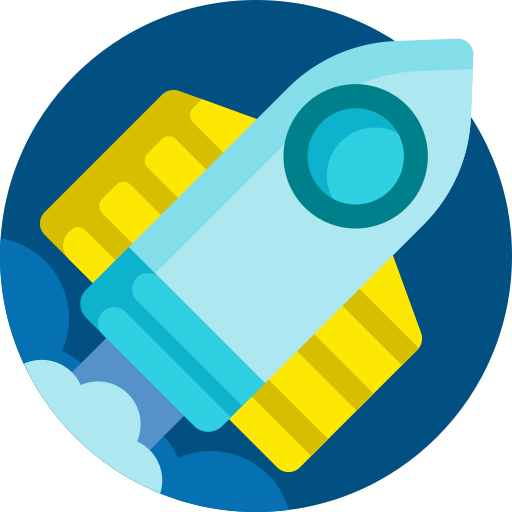

# **MEC3079S: Control Systems**

# Chapter 2 - Signals and systems

## 2.1 Introduction

In this course we will consider a **system** as a mapping between **signals**. In other words, a system will transform some **input signal** into a corresponding **output signal***. *Given a time-dependent input signal of $u(t)$, and output signal, $y(t)$, the corresponding system is defined by a map $\hat{p}$, where

$y(t)={\hat{p}}(u(t))$.

Some important things to consider for this course are that:

- The **system **is uniquely described by its input-output mapping.

- **Input signals** can be thought of as signals that can be manipulated (either directly or indirectly).

- **Output signals **are the result of how the system responds to a specific input signal.

- If a system only has a one-dimensional input and one-dimensional output (neither signal is a vector), we call this type of system a **single-input-single-output **(SISO) system. We will only consider SISO systems in this course. 

A visual representation of this input-output relationship is shown in Figure 2.1 in the form a simple block diagram. We will cover block diagrams in detail in Chapter 3.

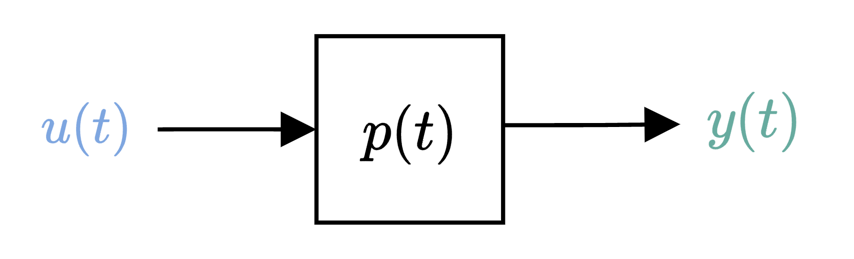

**Figure 2.1: **Input-output relationship of a system expressed in block diagram form.

### 2.1.1 Convolution

Strictly speaking, $y(t)$ is the result of **convolving** $p(t)$ and $u(t)$

$y(t)=p(t) \ast u(t) = \int_{-\infty}^{\infty}p(\tau)u(t-\tau)d\tau$,

where $\ast$ denotes the **convolution** operator. It is defined as the integral of the product of the two signals after one has been reversed and shifted (not simple multiplication!). Fortunately, we will not explore this in detail in this course. As you will see later, we can represent the above relationship in a different domain, which allows us to multiply signals instead of convolve them!

### 2.1.2 System types

Depending on how $\hat{p}$ maps $u(t)$ to $y(t)$, we can classify the system in different ways. Some examples include:

- Static (memoryless) vs dynamic.

- Linear vs nonlinear.

- Causal vs acausal.

- Time-invariant vs time-variant.

We will only consider **causal, linear time-invariant (LTI)** systems in this course. Note that the systems we work with may still be static or dynamic, but in both cases they can still be causal and LTI. The properties of causal LTI systems are given in the follow section.

## 2.2 Properties of causal and LTI systems

### 2.2.1 Causality

A system is causal if the output of the system at time $t_n$ is only dependent on the input signal behaviour for $t\leq t_n$. In other words, a system is causal if and only if the *future* input signal does not affect the *present* output. All real-world system are causal, as energy must be applied to the system (via an input) in order for the output to respond (a soccer ball will not move until you apply a force to it with your foot).

### 2.2.2 Time-invariance

A time invariant system is a time-dependent mapping between input and output signals that is the same at any point in time. In other words, the system manipulates the input in a way that does not depend on when the system is used. More formally, if $u(t-\tau)$ is input signal $u(t)$ after being delayed by $\tau$ seconds, and $y(t)={\hat{p}}(u(t))$, then a time-invariant system requires that

${\hat{p}}(u(t-\tau))=y(t-\tau)$.

That is, the output will respond to the input signal in the exact same *manner*, but the response will take place once the input signal is applied.

### 2.2.3 Linearity

A system is linear if it is both **additive **and **homogeneous**.

#### Additivity

A system is **additive **if mapping the sum of multiple input signals is equivalent to sum of the outputs after mapping each input individually

${\hat{p}}(u_1(t)+u_2(t))=\hat{p}(u_1(t))+\hat{p}(u_2(t))=y_1(t)+y_2(t)$.

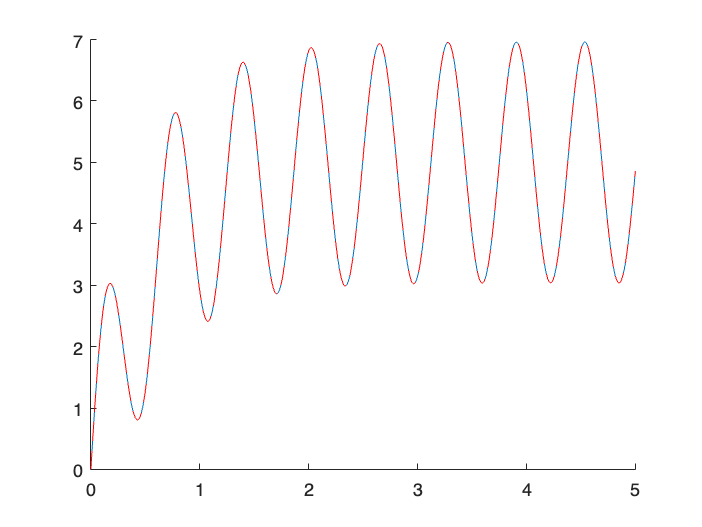

t = linspace(0,5,1000); 
u1 = sin(10*t);
u2 = 5*t;

s = tf('s');
P = s/(1+s/2);

y1 = lsim(P,u1,t);
y2 = lsim(P,u2,t);
y12 = lsim(P,u1+u2,t);

figure,hold on
plot(t,y12)
plot(t,y1+y2,'r--')

Understanding the code above is not important now, but the result is — the two systems have the exact same response as shown in the figure, based on the additivity property.

#### Homogeneity

A system is **homogeneous ** if scaling the input signal by an amount of $k$ always results in the output signal also being scaled by $k$

$\hat{p}(ku(t))=k\hat{p}(u(t))=k y(t)$.

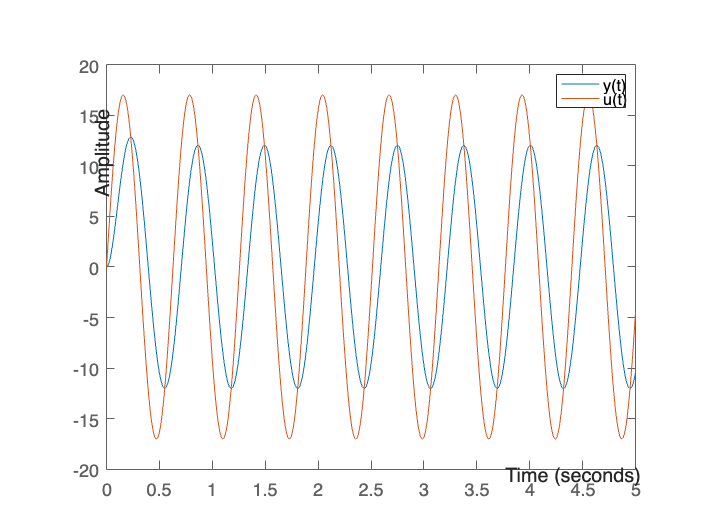

t = linspace(0,5,1000);
k = 17;
u = k*sin(10*t);

P = 1/(1+s/10);

figure,hold on
lsim(P,u,t)
plot(t,u)
legend('y(t)','u(t)')

Regardless of the constant $k$ above, the input and output relative scales remain the same, implying that our system is homogeneous.

Adding the additive and homogeneous properties together, a system is **linear** if, for all signals $u_1(t)$, $u_2(t)$, and scalars $\alpha,\beta \in \mathbb{R}$,

$\hat{p}(\alpha u_1(t)+\beta u_2(t))=\alpha\hat{p}(u_1(t))+\beta\hat{p}(u_2(t))=
\alpha y_1(t)+\beta y_2(t)$.

This result can extend to any number of inputs and scalars.

## 2.3 Differential equations

### 2.3.1 Definition

So far, we have used the mapping function $\hat{p}$ to describe the system, but an explicit means of representing how a system behaves is to use differential equations. 

**Figure 2.2: **Input-output relationship of a system expressed in block diagram form.

However, as engineers, the use of **differential equations** may be more familiar to us. Assuming the system is linear time-invariant, the system input, $u(t)$, and corresponding system output of $y(t)$ can be related by an ordinary differential equation of the form

$b_0y(t)+b_1\frac{d}{dt}y(t)+b_2\frac{d^2}{dt^2}{y}(t)+...+b_n\frac{d^n}{dt^n}y(t) =
a_0u(t)+a_1\frac{d}{dt}u(t)+a_2\frac{d^2}{dt^2}{u}(t)+...+a_m\frac{d^m}{dt^m}u(t)$,

where $a_i$ and $b_i$ are real constants, and $m\leq n$ for the system to be causal (more on this later).

#### Example

Consider the first-order differential equation

$2y(t)+\dot{y}(t)=3u(t)$,

which, based on the generalised ordinary differential equation, implies that $b_0=2$, $b_1=1$, $a_0=3$, $b_2=b_3=...=b_n=0$, and $a_1=a_2=...=a_m=0$.

### 2.3.2 Issues with differential equations

- If two systems are connected (in series for example), the resulting relationship very quickly becomes even more complex.

- It is very difficult to to determine $y(t)$ as a result of arbitrary $u(t)$ when using differential equations to model the system. However, numerical integration approaches, such as *Runge-Kutta*, exist that can give us good approximations.

## 2.4 Laplace transforms

### 2.4.1 Definition

Recall that the single-sided Laplace transform of a locally integrable function $f(t)$ is 

    $F(s) = \mathcal{L}\{f(t)\} =\int_{0}^{\infty} f(t) e^{-st} \ dt$,

where $s=\sigma+j\omega$ is a complex variable: $s\in\mathbb{C}$. $F(s)$ is therefore the Laplace transform of $f(t)$, which requires that the integral above exists.

Note that the negative time component of $f(t)$ does not affect the Laplace transform, as the integral is only evaluated for $t\in[0~\infty)$. We will make use of *upper-case* symbols, e.g $F(s)$, to show that the signal is represented in the Laplace domain and lower-case symbols, e.g. $f(t)$, to indicate time-domain signals (there will be some exceptions along the way based on engineering convention!).

We can use `MATLAB`'s [`symbolic toolbox`](https://www.mathworks.com/products/symbolic.html) to evaluate the Laplace transform as shown in the code block below (useful if you want to check your hand calculations!).

clear %clears all variables from the MATLAB workspace
syms a b t s    %define symbolic (algebraic) variables

f(t) = t    %define a symbolic (algebraic) function with respect to time parameter t

$$f(t) = t$$

F(s) = laplace(f(t),s) %determine the laplace transform of f(t)

$$F(s) = \frac{1}{s^{2}}$$

We can also visualise the time-domain behaviour of these functions using the following code.

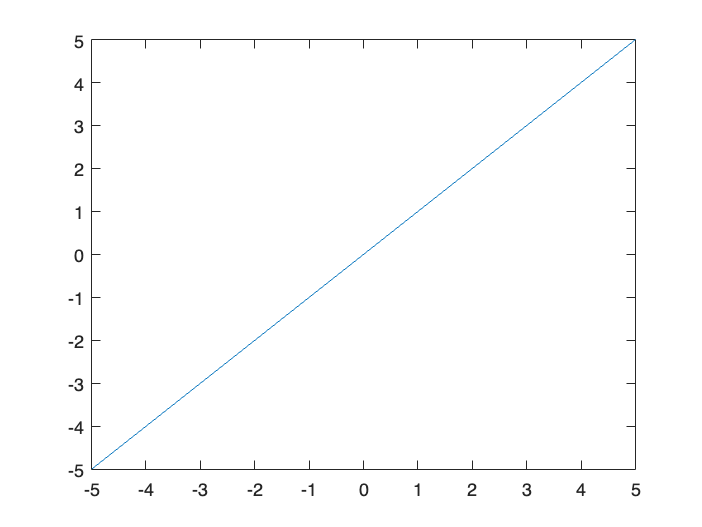

a = -1;
b = 3;
figure
fplot( eval(f(t)) ) %time-domain plot of function f(t)

### 2.4.2 Properties of Laplace transforms

Laplace transforms have several important properties that can be derived from the definition. Some of the main properties are shown in Table 2.1. 

**Table 2.1: **Properties of Laplace transforms


$$\left.
\begin{array}{lll}
\textbf{Name} & \textbf{Time domain signal} & \textbf{Laplace doman signal}
\\
\text{Time derivative} \quad& \dot{f}(t) \quad & sF(s) - f(0)
\\
n^{th}~ \text{time derivative} \quad& \frac{d^n}{dt^n}f(t) \quad & s^nF(s)-\sum_{k=1}^ns^{n-k}f^{k-1}(0)
\\
\text{Time integral} \quad& \int_0^t f(\tau) d\tau \quad & \frac{F(s)}{s}
\\
\text{Frequency shift} \quad& e^{at} f(t) \quad & F(s-a)
\\
\text{Time shift} \quad& f(t-a) \quad & e^{-as} F(s)
\\
\text{Time scaling} \quad& f(at) \quad & \frac{1}{a}F\left( \frac{s}{a}\right)
\\
\text{Time domain convolution} \quad &  f(t)*g(t) & F(s) G(s)
\\
\text{Homogeneous} \quad &  kf(t) & kF(s)
\\
\text{Additive} \quad &  f_1(t)+f_2(t) & F_1(s)+F_2(s)
\end{array}
\right.
$$


#### **Additivity**

The Laplace transform of the sum of multiple signals is equivalent to sum of the individually Laplace transformed signals. This is know as **additivity**:

$\mathcal{L} \{ f_1(t)+f_2(t) \}=\mathcal{L} \{ f_1(t)\}+\mathcal{L}\{f_2(t) \}=F_1(s)+F_2(s)$.

#### **Homogeneity**

The Laplace transform of a scaled signal is equivalent to the Laplace transform of the signal without scaling, multiplied by the scaling factor. This is referred to as **homogeneity**.

$\mathcal{L} \{ kf(t) \}=k\mathcal{L} \{ f(t) \}=kF(s)$.

#### Linearity 

An operator is linear if it is both **additive **and **homogeneous**.The Laplace transform is a *linear operator, *which means that we can simultaneously make use of our **homogeneous** and **additive** properties, namely

$\mathcal{L} \{ \alpha f_1(t)+\beta f_2(t)\}=\alpha \mathcal{L}\{ f_1(t)\}+\beta \mathcal{L} \{f_2(t)\}=\alpha F_1(s)+\beta F_2(s)$.

This property is applicable to any number of summed signals without loss of generality.

#### **Multiplication in the Laplace domain**

As shown in the table above, *convolution* in the time domain corresponds to **multiplication** in the Laplace domain. This means that given our input-output convolution relationship from before of 

$y(t)=p(t) \ast u(t)$,

we can find the corresponding output signal in the Laplace domain as

 
$$\begin{array}{rl}
Y(s) &= \mathcal{L}\{y(t)\}, \\ 
&= \mathcal{ L}\{p(t) \ast u(t) \}, \\ 
&= \mathcal{ L}\{p(t)\} \mathcal{L}\{ u(t) \}, \\
&= P(s)U(s).
\end{array}$$


As we will see later, this substantially simplifies the modeling stage when multiple systems interact with each other.

#### Time shift

Given a function $f(t)$, where $f(t)=0,\forall t<0$, the corresponding Laplace transform is known to be $F(s) = \mathcal{L}\{f(t)\}$. If $f(t)$ is now shifted in time by $\tau$ seconds, then only the phase angle of the Laplace transform is affected. Mathematically this is represented as

$\mathcal{L}\{f(t-\tau)\}=e^{-s\tau}F(s)$.

A simple example is shown below.

%Example
clear
syms t s

tau = 3; %time delay

%f1
f1(t) = heaviside(t)  %step function without delay

$$f1(t) = \mathrm{heaviside}\left(t\right)$$

F1(s) = laplace(f1(t),s) %determine the laplace transform of f(t)

$$F1(s) = \frac{1}{s}$$


f2(t) = heaviside(t-tau)  %step function with delay

$$f2(t) = \mathrm{heaviside}\left(t-3\right)$$

F2(s) = laplace(f2(t),s) %determine the laplace transform of f(t)

$$F2(s) = \frac{{\mathrm{e}}^{-3\,s}}{s}$$

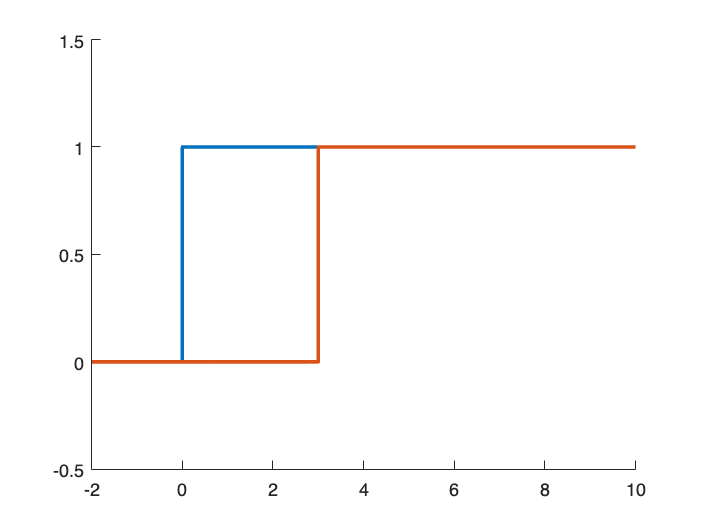


figure,hold on
fplot( eval(f1(t)),[-2 10],lineWidth=2 ) %time-domain plot of function f1(t)
fplot( eval(f2(t)),[-2 10],lineWidth=2 ) %time-domain plot of function f2(t)

ylim([-0.5,1.5])

### 2.4.3 Converting differential equations to Laplace transforms

If we are given (or can derive) linear differential equations that describe our system, we can make use of the Laplace transform to find the relationship between our input and output signals. Importantly, we need to know what our initial conditions are in order to apply the appropriate transform.

Recall that the Laplace transform of a time derivative can be computed through integration by parts as

    
$$\begin{array}{rl}
\mathcal{L}\{\dot{f}(t)\} &= \int_{0}^{\infty}  \dot{f}(t) e^{-st} \ dt
\\
&= \left. f(t) e^{-st} \ \right\vert_0^\infty - \int_{0}^{\infty}  f(t) \left( -s  e^{-st}) \ dt
\\
&= - f(0) + sF(s).
\end{array}$$


If we are able to set (by adjusting our axes if need be) our initial condition, $f(0)$, to zero, we end up with the simplified mapping of 

$\mathcal{L}\{\dot{f}(t)\}=sF(s)$,

where $F(s)$ is the Laplace transform of $f(t)$, and $f(0)$ is the initial condition of $f(t)$ (the value of $f(t)$ when $t=0$). 

We can think of the above relationship as capturing the incremental behaviour of the system, as the initial conditions are effectively inconsequential for our understanding of the *dynamic* system. Under the assumption that the initial conditions are equal to zero, the Laplace transform of the $k^{th}$ derivative of $f(t)$ is generalised as

$
\mathcal{L}\{\frac{d^k}{dt^k}f(t)\}=s^kF(s)

$.

Given the relationships above, and assuming our initial conditions have been set to zero, we can convert our differential equation of 


$$b_0y(t)+b_1\frac{d}{dt}y(t)+b_2\frac{d^2}{dt^2}{y}(t)+...+b_n\frac{d^n}{dt^n}y(t) =
a_0u(t)+a_1\frac{d}{dt}u(t)+a_2\frac{d^2}{dt^2}{u}(t)+...+a_m\frac{d^m}{dt^m}u(t)$$


into a corresponding equation that is solely a function of the Laplace operator $s$

$b_0Y(s)+b_1sY(s)+b_2s^2{Y}(s)+...+b_ns^nY(s) =
a_0U(s)+a_1sU(s)+a_2s^2{U}(s)+...+a_ms^mU(s)$.

In other words, whenever we see a $\frac{d^k}{dt^k}y(t)$ term we simply replace it with $s^kY(s)$. Note that we technically also made use of $
\mathcal{L}\{\frac{d^0}{dt^0}f(t)\}=s^0F(s)=F(s)

$ when finding the Laplace transform of $y(t)$. 

#### Example

*Consider the first-order differential equation from before of*

$2y(t)+\dot{y}(t)=3u(t)$*,*

*with zero initial conditions (*$y(0)=\dot{y}(0)=u(0)=0$*). Determine the corresponding Laplace transformed equation.*

Applying the Laplace transform rule of $
\mathcal{L}\{\frac{d^k}{dt^k}f(t)\}=s^kF(s)

$ to both sides of the equation above yields

$2Y(s)+sY(s)=3U(s)$.

## 2.5 Transfer functions

### 2.5.1 Definition

A **transfer function** is a compact way of representing the relationship between the input signal entering a system, and its output signal. It's a mathematical model that captures the linear time invariant dynamics of a system. Formally, a transfer function of a system, $P(s)$, is defined as the ratio of its Laplace transformed output signal, $Y(s)$, and the Laplace transformed input signal, $U(s)$, namely

$P(s)=\frac{Y(s)}{U(s)}$.

Based on our understanding of multiplication in the Laplace domain, this means that if we know $P(s)$, we can then obtain $Y(s)$ by multiplying through with $U(s)$

$Y(s)=P(s){U(s)}$.

At the moment we do not know what to do with this information, but things will become clearer in due time! A block diagram representation of this result is shown in Figure 2.3.

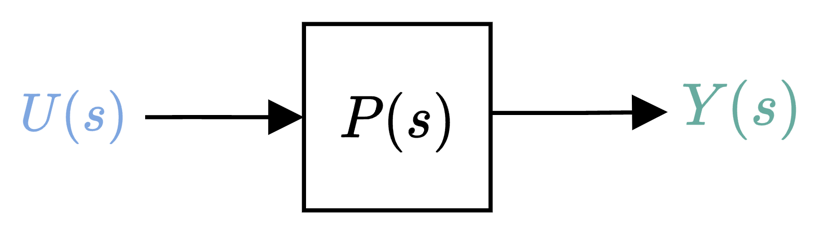

**Figure 2.3: **Input-output relationship of a system expressed in block diagram form.

Note that when describing signals and systems in the Laplace domain, the block diagram above is equivalent to the multiplication operation of $U(s)P(s)=Y(s)$.

### 2.5.2 Deriving the transfer function from a differential equation

If we rearrange our Laplace transformed equation from before of


$$b_0Y(s)+b_1sY(s)+b_2s^2{Y}(s)+...+b_ns^nY(s) =
a_0U(s)+a_1sU(s)+a_2s^2{U}(s)+...+a_ms^mU(s)$$


as follows

$(b_0+b_1s+b_2s^2+...+b_ns^n)Y(s) =
(a_0+a_1s+a_2s^2+...+a_ms^m)U(s)$,

and solve for the system output in the Laplace domain, $Y(s)$, we arrive at an explicit function of the system input, $U(s)$

$Y(s)=
\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n }U(s)$.

The ratio of the polynomials in $s$ that arises in this equation matches our definition of the transfer function model, and represents the transfer function description of our system $P(s)$, which we will denote as

$P(s)=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n }=\frac{Y(s)}{U(s)}$.

The system output signal (in the Laplace domain) is then concisely related to the corresponding input signal via $P(s)$

$Y(s)=P(s)U(s)$. 

#### Example

*Consider the first-order differential equation from before of*

$2y(t)+\dot{y}(t)=3u(t)$*,*

*with zero initial conditions (*$y(0)=\dot{y}(0)=u(0)=0$*). Determine *$Y(s)$*.*

Applying the Laplace transform rule of $
\mathcal{L}\{\frac{d^k}{dt^k}f(t)\}=s^kF(s)

$ to both sides of the equation above yields

$2Y(s)+sY(s)=3U(s)$.

We then factor out the common signals as

$\left[2+s\right]Y(s)=3U(s)$.

We can then determine the Laplace domain model of our system using


$$\begin{array}{ll} 
P(s)
&=\frac{Y(s)}{U(s)}, \\ 
&=\frac{3}{2+s}.\\ 
\end{array}$$


The output response in the Laplace domain follows as


$$\begin{array}{ll} 
Y(s)&=P(s)U(s), \\ 
&=\frac{3}{2+s}U(s),\\ 
\end{array}$$


which will be dependant on signal $U(s)$.

### 2.5.3 Deriving the transfer function from input-output data

The transfer function is formally defined as the ratio of the Laplace transform of the output of a system to the Laplace transform of the input. This implies that we can also find $P(s)$ if we know (or can measure) $y(t)$ and $u(t)$ and are then able to take the ratio of the Laplace transforms. In other words, 

$P(s)=\frac{Y(s)}{U(s)}=\frac{\mathcal{L}\{y(t)\}}{\mathcal{L}\{{u(t)}\}}$.

This approach to determining $P(s)$ is important, as we will not always have a differential equation handed to us that describes the system. We may actually need to determine how our system is described by applying some input signal, $u(t)$, to the system, seeing how the output, $y(t)$, responds, and then finding the ratio of the Laplace transforms of the two signals.

#### Example

*A signal *$u(t)=2,\forall t\geq 0$* is applied to an unknown system *$P(s)$*, and the resulting output response is determined to be *$y(t)=10t^2$*. Determine *$P(s)$*. *

Based on this information, we can determine our system model to be


$$\begin{array}{rl} 
P(s)
&=\frac{Y(s)}{U(s)}, \\ 
&=\frac{\mathcal{L}\{y(t)\}}{\mathcal{L}\{u(t)\}},\\
&=\frac{\mathcal{L}\{10t^2\}}{\mathcal{L}\{2\}},\\
&=\frac{\frac{20}{s^3}}{\frac{2}{s}},\\
&=\frac{10}{s^2}.\\
\end{array}$$


Note that we had to use the Laplace transform table shown in Table 2.2. 

We can check our working using the code below.

%Example
clear
syms t s

y(t) = 10*t^2   %algebraic y(t)

$$y(t) = 10\,t^{2}$$

u(t) = 2+0*t    %algebraic u(t)

$$u(t) = 2$$


Y(s) = laplace( y(t),s )    %Laplace transform of y(t)

$$Y(s) = \frac{20}{s^{3}}$$

U(s) = laplace( u(t),s )    %Laplace transform of u(t)

$$U(s) = \frac{2}{s}$$

P(s) = Y(s)/U(s)    %P(s) 

$$P(s) = \frac{10}{s^{2}}$$

## 2.6 Inverse Laplace transforms

### 2.6.1 Definition

The Laplace transform is useful when mapping time-domain signals in the Laplace transform, and as the name implies, the **inverse Laplace transform** maps signals from the Laplace domain into the time domain. The inverse Laplace transform is denoted as

    $f(t) = \mathcal{L}^{-1} \{ F(s) \}=\frac{1}{2\pi j}\oint_{c}Y(s)e^{st}ds$.

Evaluating the equation above is not trivial, but fortunately we will not be expected to use it directly in this course. We will instead make use of a Laplace transform table, as shown in the following section.

### 2.6.2 Laplace transform table

Forward and inverse Laplace transforms are usually found by appealing to a transform table, such as the one shown in Table 2.2. 

**Table 2.2: **Laplace transform table


$$\left.
\begin{array}{lll}
\textbf{Name} & {\bf f(t)} & {\bf F(s)}
\\
\text{Impulse function} \quad& a\delta(t) \quad & a
\\
\text{Step function} \quad& a \quad & \frac{a}{s}
\\
\text{Ramp function} \quad& at \quad & \frac{a}{s^2}
\\
\text{Parabolic function} \quad& \frac{1}{2}at^2 \quad & \frac{a}{s^3}
\\
\text{$n^{th}$-order function} \quad& \frac{1}{n!}at^{n} \quad & \frac{a}{s^{n+1}}
\\
\text{Exponential decay} \quad& ae^{-bt} \quad & \frac{a}{s+b}
\\
\text{Sinusoid} \quad &  a\sin(\omega t) & \frac{a\omega}{s^2+\omega^2}
\\
\text{Cosinusoid} \quad &  a\cos(\omega t)& \frac{as}{s^2+\omega^2}
\end{array}
\right.
$$


Using a Laplace transform table allows us to quickly move from a time-domain signal, $f(t)$, to the corresponding Laplace domain signal, $F(s)$. We will explore these transforms in more detail in **Chapter 3**.

#### Example 1

*Determine the Laplace transform of *$y(t)=2e^{-3t}$*.*

We can easily find $Y(s)$ by consulting our transform table above, namely

$Y(s)=\mathcal{L}\{2e^{-3t}\}=\frac{2}{s+3}$.

%Example 1
clear
syms t s

y(t) = 2*exp(-3*t)

$$y(t) = 2\,{\mathrm{e}}^{-3\,t}$$

Y(s) = laplace( y(t),s )

$$Y(s) = \frac{2}{s+3}$$

#### Example 2

*Determine the inverse Laplace transform of *$Y(s)=\frac{1}{s/10+1}$*. *

As before, we can make use of the transform table to determine $y(t)$, but we must first put the numerator and denominator polynomials of $Y(s)$ in the form that matches that of the table:

$Y(s)=\frac{1}{s/10+1}=\frac{10}{s+10}$.

The inverse Laplace transform follows as

$y(t)=\mathcal{L}^{-1}\{Y(s)\}=\mathcal{L}^{-1}\{\frac{10}{s+10}\}=10e^{-10t}$.

%Example 2
clear
syms t s

Y(s) = 1/(s/10+1)

$$Y(s) = \frac{1}{\frac{s}{10}+1}$$

y(t) = ilaplace( Y(s),t )   %determine the inverse Laplace transform, y(t), given Y(s)

$$y(t) = 10\,{\mathrm{e}}^{-10\,t}$$

### 2.6.3 Properties of inverse Laplace transforms

The inverse Laplace operator has the same properties as that of the Laplace operator. By extension, our properties table from before, shown below in Table 2.3 sake of convenience, can be used to understand the mapping from the Laplace domain to the time domain.

**Table 2.3: **Properties of Laplace transforms


$$\left.
\begin{array}{lll}
\textbf{Name} & \textbf{Time domain signal} & \textbf{Laplace doman signal}
\\
\text{Time derivative} \quad& \dot{f}(t) \quad & sF(s) - f(0)
\\
n^{th}~ \text{time derivative} \quad& \frac{d^n}{dt^n}f(t) \quad & s^nF(s)-\sum_{k=1}^ns^{n-k}f^{k-1}(0)
\\
\text{Time integral} \quad& \int_0^t f(\tau) d\tau \quad & \frac{F(s)}{s}
\\
\text{Frequency shift} \quad& e^{at} f(t) \quad & F(s-a)
\\
\text{Time shift} \quad& f(t-a)u(t-a) \quad & e^{-as} F(s)
\\
\text{Time scaling} \quad& f(at) \quad & \frac{1}{a}F\left( \frac{s}{a}\right)
\\
\text{Time domain convolution} \quad &  f(t)*g(t) & F(s) G(s)
\\
\text{Homogeneous} \quad &  kf(t) & kF(s)
\\
\text{Additive} \quad &  f_1(t)+f_2(t) & F_1(s)+F_2(s)
\end{array}
\right.
$$


#### Linearity 

By definition of the Laplace transform's linearity property, the inverse Laplace transform is also a linear operator*, *which means that we can make use of our homogeneous and additive properties as before

$\mathcal{L}^{-1} \{ \alpha F_1(s)+\beta F_2(s)\}=\alpha \mathcal{L}^{-1}\{ F_1(s)\}+\beta \mathcal{L}^{-1} \{F_2(s)\}=\alpha f_1(t)+\beta f_2(t)$.

This property comes in handy when we want to determine time-domain output signals from transfer function descriptions. Specifically, if we can convert a complicated transfer function into a sum of less complex transfer functions, we can then just apply the inverse Laplace transform operate to each individual element and then summate all terms to determine the time-domain signal. This process is outlined in detail in **Chapter 5**, but a simple example is provided below.

#### Example

*Determine the inverse Laplace transform of *$Y(s)=\frac{1}{s/10+1}+\frac{2}{s+3}$*.*

We know the inverse Laplace transform of $\frac{1}{s/10+1}$ from **Example 2 **above, as well as the inverse Laplace transform of $\frac{2}{s+3}$ from **Example 1**. Using our understanding of the linearity property, we can determine $y(t)$ as


$$\begin{array}{rl} 
y(t) &=\mathcal{L}^{-1}\{Y(s)\},\\
&= \mathcal{L}^{-1}\{\frac{1}{s/10+1}+\frac{2}{s+3}\},\\
&= \mathcal{L}^{-1}\{\frac{1}{s/10+1}\}+\mathcal{L}^{-1}\{\frac{2}{s+3}\},\\
&= 10e^{-10t}+2e^{-3t}.
\end{array}$$


%Example 2
clear
syms t s

Y(s) = 1/(s/10+1)+2/(s+3)

$$Y(s) = \frac{2}{s+3}+\frac{1}{\frac{s}{10}+1}$$

y(t) = ilaplace( Y(s),t )   %determine the inverse Laplace transform, y(t), given Y(s)

$$y(t) = 2\,{\mathrm{e}}^{-3\,t}+10\,{\mathrm{e}}^{-10\,t}$$